usage: teamwork for week 7

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.4.18

clear all; close all; clc

**1.  下面代码是用来计算下述函数：**


$$f(x)=\begin{cases}
    0,& x<0\\
    x, & 0\leq x\leq 1\\
    2-x,& 1\leq x \leq 2\\
    0, & x>2
    \end{cases}$$


**请改正其中的错误。**

解：

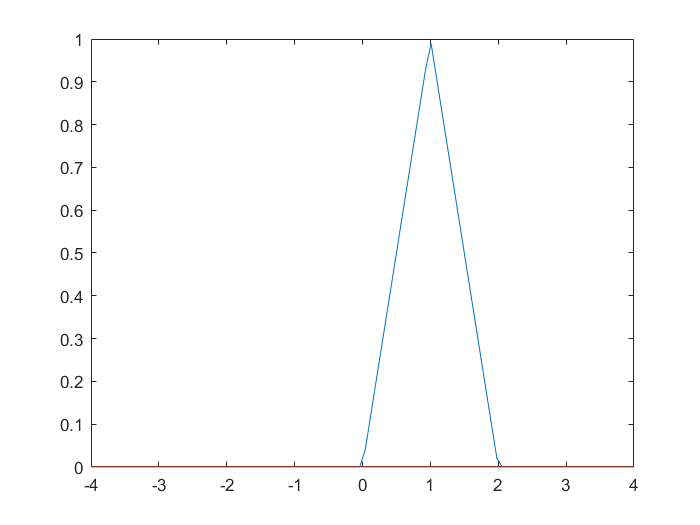

clear all;
x = linspace(-4,4);             % matlab内置的生成线性间距向量的函数为linspace
N = length(x);                  % 调用length函数需要在x外加括号
f = zeros(N);                   % 提前为f向量设定好内存空间
for j = 1:N                     % 表示一个迭代器向量从1到N时应使用冒号:，而不是分号;
    if x(j)>=0 && x(j)<=1	% matlab中使用&&表示条件与
        f(j) = x(j);
    elseif x(j)>1 && x(j)<2     % 根据题目函数应为&&表示条件与
        f(j) = 2 - x(j);        % 用x(j)表示x向量中第j个元素
    else
        f(j) = 0;               % 不使用扩展包，无法使用zero关键字，故使用0代替
    end
end
plot(x, f)

**2. 编写一个函数文件产生希尔伯特矩阵(Hilbert matrix):**


$$H = \pmatrix{
   1 & \frac{1}{2} & \frac{1}{3} & \cdots &\frac{1}{n} \cr 
   \frac{1}{2} & \frac{1}{3} & \cdots &
   \cdots& \frac{1}{n+1}\cr
   \vdots &\vdots &\vdots& \vdots& \vdots \cr 
   \frac{1}{n} & \frac{1}{n+1} & \cdots & \cdots& \frac{1}{2n-1}}$$


**该函数只需要一个输入变量，即矩阵的阶数**$$n$$**, 输出变量有两个：**$$n\times n$$**的希尔伯特矩阵和它的行列式。 使用`det`验证对于**$$n=1,2,3,4,5$$**, 希尔伯特矩阵**$$H_n$$**的行列式分别是**$$1, 12, 2160, 6048000, 266716800000$$**的倒数。**

解：

clear all;
[m_1, d_1] = Hilbert_matrix(1);

1x1 Hibert matrix:
     1

1x1的希尔伯特矩阵的行列式为: 1.000000
其倒数为: 1


[m_2, d_2] = Hilbert_matrix(2);

2x2 Hibert matrix:
   1.000000000000000   0.500000000000000
   0.500000000000000   0.333333333333333

2x2的希尔伯特矩阵的行列式为: 0.083333
其倒数为: 12


[m_3, d_3] = Hilbert_matrix(3);

3x3 Hibert matrix:
   1.000000000000000   0.500000000000000   0.333333333333333
   0.500000000000000   0.333333333333333   0.250000000000000
   0.333333333333333   0.250000000000000   0.200000000000000

3x3的希尔伯特矩阵的行列式为: 0.000463
其倒数为: 2160


[m_4, d_4] = Hilbert_matrix(4);

4x4 Hibert matrix:
   1.000000000000000   0.500000000000000   0.333333333333333   0.250000000000000
   0.500000000000000   0.333333333333333   0.250000000000000   0.200000000000000
   0.333333333333333   0.250000000000000   0.200000000000000   0.166666666666667
   0.250000000000000   0.200000000000000   0.166666666666667   0.142857142857143

4x4的希尔伯特矩阵的行列式为: 0.000000
其倒数为: 6048000


[m_5, d_5] = Hilbert_matrix(5);

5x5 Hibert matrix:
   1.000000000000000   0.500000000000000   0.333333333333333   0.250000000000000   0.200000000000000
   0.500000000000000   0.333333333333333   0.250000000000000   0.200000000000000   0.166666666666667
   0.333333333333333   0.250000000000000   0.200000000000000   0.166666666666667   0.142857142857143
   0.250000000000000   0.200000000000000   0.166666666666667   0.142857142857143   0.125000000000000
   0.200000000000000   0.166666666666667   0.142857142857143   0.125000000000000   0.111111111111111

5x5的希尔伯特矩阵的行列式为: 0.000000
其倒数为: 266716800000


可以验证对于$$n=1,2,3,4,5$$的希尔伯特矩阵的行列式分别为$$1, 12, 2160, 6048000, 266716800000$$的倒数。

[m_3, d_3] = Hilbert_matrix(3)

3x3 Hibert matrix:
    1.0000    0.5000    0.3333
    0.5000    0.3333    0.2500
    0.3333    0.2500    0.2000

3x3的希尔伯特矩阵的行列式为: 0.000463
其倒数为: 2160


m_3 =     1.0000    0.5000    0.3333
    0.5000    0.3333    0.2500
    0.3333    0.2500    0.2000


d_3 = 4.6296e-04

norm(m_3, inf)

ans = 1.8333

**3. 以下是Fibonacci正弦函数和Fibonacci余弦函数的定义**

  
$$ $$
   \text{sFs}(x)=\frac{\gamma^x-\gamma^{-x}}{\sqrt{5}},\;\text{cFs}(x)=\frac{\gamma^x+\gamma^{-x}}{\sqrt{5}}
   $$   $$


**   其中**$$\gamma=(1+\sqrt{5})/2$$**. **

**复数类正弦Fibonacci函数由下式定义**

   
$$$$
   \text{cqsF}(x,n)=\frac{\gamma^x-\cos(n\pi x)\gamma^{-x}}{\sqrt{5}}+i\frac{\sin(n\pi x)\gamma^{-x}}{\sqrt{5}}
   $$$$


**(1) 使用匿名函数计算三个函数的函数值，在一张图上绘制**$$\text{sFs}(x)$$**和**$$\text{cFs}(x)$$**函数曲线，**$ $x$$**取值范围为**$$[-5,5]$$

**(2) 使用`plot3`绘制3D图形， 其中**$$x$$**取值范围为**$$[-5,5]$$**， **$$y$**值为**$$\text{cqsF}(x,5)$$**的实数部分， **$$z$$**值为**$$\text{cqsF}(x,5)$$**的虚数部分。**

解：

（1）

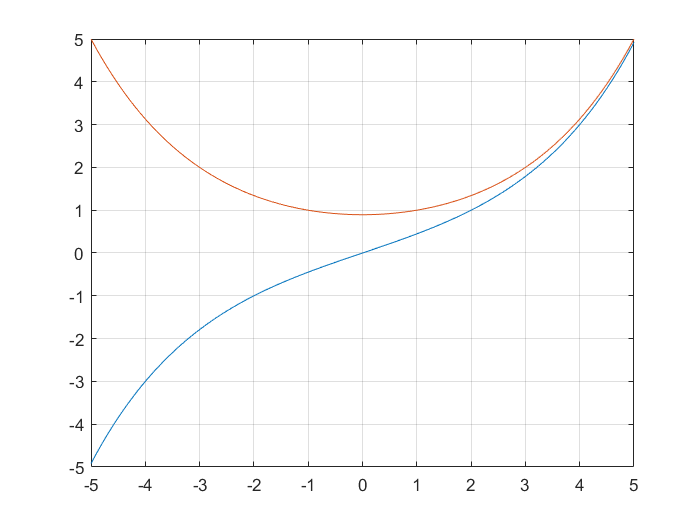

clear all;
ga = (1 + sqrt(5)) / 2;
sFs = @(x) (ga.^x - ga.^(-x))./sqrt(5);
cFs = @(x) (ga.^x + ga.^(-x))./sqrt(5);
sample_3 = linspace(-5, 5);
plot(sample_3, sFs(sample_3), sample_3, cFs(sample_3))
grid on

（2）

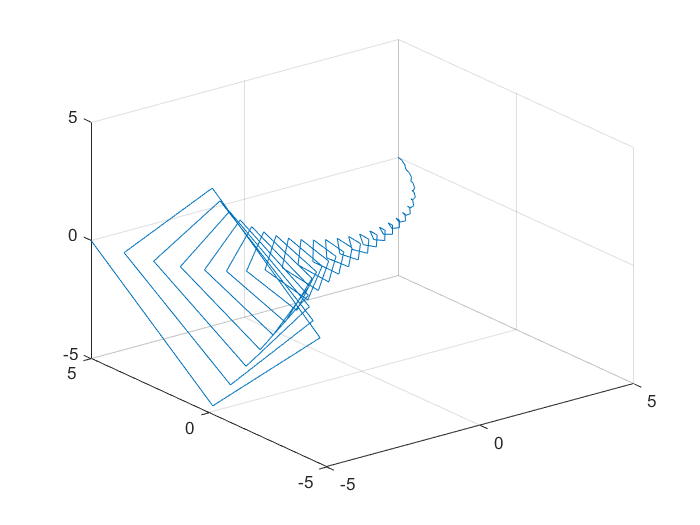

cqsF = @(x, n) (ga.^x - cos(n*pi.*x).*ga.^(-x))./sqrt(5) + 1i*sin(n*pi.*x).*ga.^(-x)./sqrt(5);
plot3(sample_3, real(cqsF(sample_3, 5)), imag(cqsF(sample_3, 5)))
grid on

**4. (选做) 使用`meshgrid`和`mesh`绘制3D图形**


$$    z = f(x,y) = (1-x^2)e^{-p} -pe^{-p}- e^{-(x+1)^2-y^2}\\
    x= -4 : 0.1 : 4,\;y =-4 : 0.1 : 4$$


**其中**$$p=x^2+y^2$$**. **

**使用`surf`和`contour`重新绘制, 并使用`subplot`将3张图沿竖直方向放置在一起。**

解：

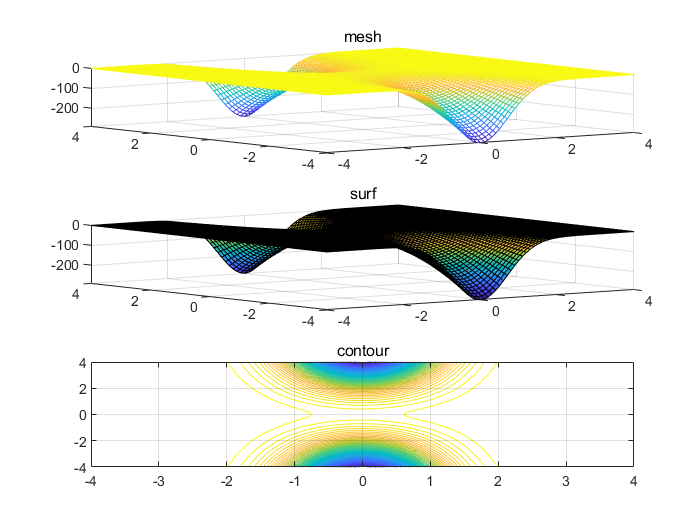

clear all;
p = @(x, y) x.^2 + y.^2;
z = @(x, y) (1 - x.^2).*exp(-p(x, y)) - p(x, y)*exp(-p(x, y)) - exp(-(x + 1).^2 - y.^2);
[x, y] = meshgrid(-4:0.1:4);
subplot(3,1,1);
mesh(x, y, z(x ,y));
title('mesh')
subplot(3,1,2);
surf(x, y, z(x, y));
title('surf')
subplot(3,1,3);
contour(x, y, z(x, y), 50);
title('contour')
grid on

**5. Illinois算法是1971年Dowell和Jarret提出的一个寻根方法**$[^1]$**， 它的想法是：**

   
$$\text{初始试探区间: 函数值在两端异号, }f_0f_1 <0\\
   \text{For }k = 1,2,\cdots\\
   x_{2} = x_1 - \frac{f_1}{f[x_{0}, x_1]}\\
   \text{- 如果 }f_1f_{2} <0, (x_{0}, f_{0}) \text{ 由 } (x_1, f_1) \text{替代}\\
   \text{- 如果 }f_1f_{2} >0, (x_{0}, f_{0}) \text{ 由 } (x_1, gf_1) \text{替代}\\
    (x_{1}, f_{1}) \text{ 由 } (x_{2}, f_{2}) \text{替代}\\
   \text{其中 }f_{0,1,2}= f(x_{0,1,2}),  f[x_0, x_1]=\frac{f_1-f_0}{x_1-x_0}\\
   g = 0.5$$


**编写程序实现Illinois算法， 求解开普勒方程**


$$   $$
   E- e \sin E =M
   $$$$


**   参数**$$e$$**取为哈雷彗星轨道的偏心率**$$e=0.96727464$$**,**$ $M=4.527594\times10^{-3}$$**, 设置精度**$$\vert \Delta E\vert< 1e-6$$**.**

**   提示： 为了测试Illinois算法， 可以先采用试验方程**$$\sin x-0.5=0$$**， 试探区间取为**$$[0,1.5]$$**, 根为**$$\pi/6$$**.**

解：

clear all;
% 试验方程
test = @(x) sin(x) - 0.5;
[x_5_test, flag_5_test] = Illinois(test,0, 1.5, 1e-6, 10000) % 用Illinois算法求得的试验方程的解

Illinois:
the root of f(x)=0 is x = 0.523599, the number of iterations is 8


x_5_test =    0.523598775599009


flag_5_test =      8


x_5_test_check = pi / 6 % 方程的真实解

x_5_test_check =    0.523598775598299


通过求解试验方程$$\sin x-0.5=0$$，可以发现Illinois算法正确得到结果$\approx0.523598$

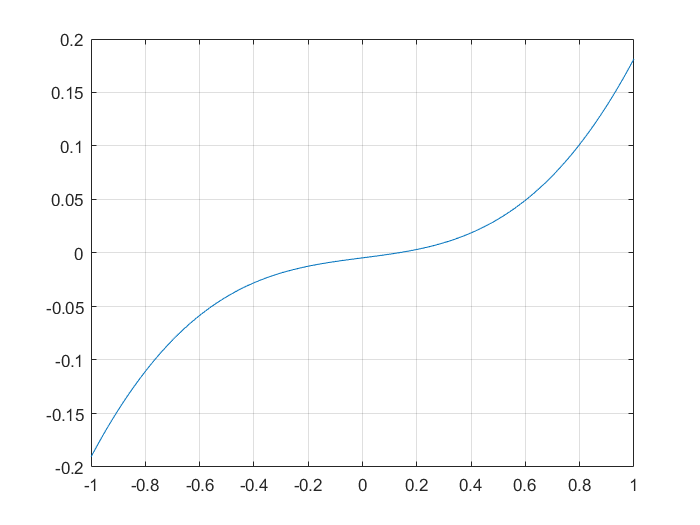

% 求解开普勒方程，先做图
e = 0.96727464;
M_test = 4.527594 * 1e-3;
f_5 = @(E) E - e*sin(E) - M_test;
sample_5 = linspace(-1, 1);
subplot(1,1,1);
plot(sample_5, f_5(sample_5))
grid on

通过作图可以发现开普勒方程的解在区间$[-0.2, 0.2]$间，故以此作为Illinois算法的初始试探区间进行求解。

[x_5, flag_5] = Illinois(f_5, -0.2, 0.2, 1e-6, 10000)

Illinois:
the root of f(x)=0 is x = 0.128023, the number of iterations is 6


x_5 =    0.128023087270730


flag_5 =      6


x_5_check = fzero(f_5, 0) % fzero验证解的正确性

x_5_check =    0.128023075406350


经过与matlab内置函数fzero求解结果的对比发现使用Illinois算法得到的结果正确 E$\approx0.128023$.

**6. 设**$$f(x)=x+2/x$$**, 请编写程序  **

**   (1)   应用**$$x=(1,2,2.5)$$**处的三个数据点进行二阶拉格朗日多项式插值求**$$f(1.5)$$**和**$$f(1.2)$$**的近似值。**

**   (2) 应用**$$x=(0.5,1,2,2.5)$$**处的四个数据点进行三阶拉格朗日多项式插值求**$$f(1.5)$$**和**$$f(1.2)$$**的近似值。**

解：

（1）

clear all;
f_6 = @(x) x + 2./x;
x_6_1 = [1 2 2.5];
y_6_1 = f_6(x_6_1);
yi_6_1_1 = LagrangeInterp(x_6_1, y_6_1, 1.5)% 用三个点进行插值

yi_6_1_1 =    2.900000000000000


yi_6_1_1_check = f_6(1.5)

yi_6_1_1_check =    2.833333333333333


e_6_1_1 = relative_e(yi_6_1_1, yi_6_1_1_check); % 求f(1.5)的插值与真值的相对误差

相对误差为: 2.352941e-02


yi_6_1_2 = LagrangeInterp(x_6_1, y_6_1, 1.2)

yi_6_1_2 =    2.936000000000000


yi_6_1_2_check = f_6(1.2)

yi_6_1_2_check =    2.866666666666667


e_6_1_2 = relative_e(yi_6_1_2, yi_6_1_2_check);% 求f(1.2)的插值与真值的相对误差

相对误差为: 2.418605e-02

从结果可以得到进行二阶拉格朗日多项式插值求得的$$f(1.5)$$相对误差为$2.35\times10^{-2}$，

$$f(1.2)$$相对误差为$2.41\times10^{-2}$。

（2）

x_6_2 = [0.5 1 2 2.5];
y_6_2 = f_6(x_6_2);
yi_6_2_1 = LagrangeInterp(x_6_2, y_6_2, 1.5) % 用四个点进行插值

yi_6_2_1 =    2.700000000000000


yi_6_2_1_check = f_6(1.5)

yi_6_2_1_check =    2.833333333333333


e_6_2_1 = relative_e(yi_6_2_1, yi_6_2_1_check);% 求f(1.5)的插值与真值的相对误差

相对误差为: -4.705882e-02


yi_6_2_2 = LagrangeInterp(x_6_2, y_6_2, 1.2)

yi_6_2_2 =    2.769600000000000


yi_6_2_2_check = f_6(1.2)

yi_6_2_2_check =    2.866666666666667


e_6_2_2 = relative_e(yi_6_2_2, yi_6_2_2_check);% 求f(1.2)的插值与真值的相对误差

相对误差为: -3.386047e-02

从结果可以得到进行三阶拉格朗日多项式插值求得的$$f(1.5)$$相对误差为$-4.70\times10^{-2}$，

$$f(1.2)$$相对误差为$-3.38\times10^{-2}$。

**7. 考虑区间**$$[0,1]$$**上的函数**$$f(x)=\sin x$$**， 确定步长**$$h$$**, 使得线性拉格朗日插值的精度为**$$10^{-6}$$**.**

解：

因为$f^{(n+1)}(x)=\Biggr\{\matrix{cos(x),n=4k\cr -sin(x),n=4k+1\cr -cos(x),n=4k+2\cr sin(x),n=4k+3}$，$M_{n+1}=max(|f^{(n+1)}(z)|)=1$

clear all;
format long
% 测试老师例题中对ln(1+x)的误差分析，求E_2
M_test = @(n) prod(1:n-1);
[h_test, E_test] = E_LI(2, M_test, 1, 0) % E_LI函数计算拉格朗日插值的精度


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


h_test =    0.500000000000000


E_test =    0.016037507477462


% 对比发现函数结果基本正确，当h=0.5时，E=0.160375

M = @(n) 1;% 恒为1的常值函数
n = 1;% n从1开始迭代
v = zeros(1, 2);
[v(1,1), v(1,2)] = E_LI(n, M, 1, 0);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


while(v(1,2) > 1e-5) % 当精度达到1e-6时停止迭代
    n = n + 1;
    [v(1,1), v(1,2)] = E_LI(n, M, 1, 0);
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

fprintf('使得线性拉格朗日插值的精度为1e-6的步长为 %f,精度为 %e', v(1), v(2))

使得线性拉格朗日插值的精度为1e-6的步长为 0.200000,精度为 1.502302e-06

可以得到当h=0.2时，E=1.502302e-06，是满足精度的数量级条件的。

**8. 给出概率积分**$$f(x)=\frac{2}{\sqrt{\pi}}\displaystyle\int_0^x e^{-t^2}dt$$**的数据表**

**    |**$ $x$ $**        | 0.46           | 0.47           | 0.48           | 0.49          |**

**    | **$$f(x)$$** | 0.4846555 | 0.4937452 | 0.5027498 | 0.5116683 |**

**用二阶多项式插值计算: **

**(1) 当**$$x=0.472$$**时，积分值等于多少？  **

**(2)  当**$$x$$**为何值时积分为0.5？    **

** 提示： 可使用`polyfit`.**

解：

（1）

clear all;
x_8_1 = [0.46 0.47 0.48 0.49];
y_8_1 = [0.4846555 0.4937452 0.5027498 0.5116683];
p = polyfit(x_8_1, y_8_1, 2);
yi_8_1 = polyval(p, 0.472)

yi_8_1 =    0.495553058000000


通过polyfit拟合得到的二阶多项式计算当$$x=0.472$$时，$y=0.4955530$。

（2）

从给出的数据表中可以看出x在区间$[0.47,0.48]$之间，事实上就是解二阶多项式等于0.5的方程，使用本作业中的Illinois算法进行求解，以$x_0=0.47,x_1=0.48$作为初始试探区间。

[x_8_2, ~] = Illinois(@(x) polyval(p, x) - 0.5, 0.47, 0.48, 1e-6, 10000);

Illinois:
the root of f(x)=0 is x = 0.476936, the number of iterations is 4


解得$x\approx0.476936$。

**********************************************functions**************************************************

Hilbert matrix：$H = \pmatrix{
   1 & \frac{1}{2} & \frac{1}{3} & \cdots &\frac{1}{n} \cr 
   \frac{1}{2} & \frac{1}{3} & \cdots &
   \cdots& \frac{1}{n+1}\cr
   \vdots &\vdots &\vdots& \vdots& \vdots \cr 
   \frac{1}{n} & \frac{1}{n+1} & \cdots & \cdots& \frac{1}{2n-1}}$

args:

    n：矩阵的阶数$$n$$

output:

    m：$$n\times n$$的希尔伯特矩阵

    d：$$n\times n$$希尔伯特矩阵的行列式

function [m, d] = Hilbert_matrix(n)
    m = ones(n, n); % 为希尔伯特矩阵分配内存空间
    for k = 1:n
        m(k, :) = m(k, :) ./ (k:(k+n-1)); % 每行对应元素1除以从k到k+n-1的向量
    end
    d = det(m); % 求希尔伯特矩阵的行列式
    fprintf("%dx%d Hibert matrix:\n", n, n)
    disp(m)
    fprintf("%dx%d的希尔伯特矩阵的行列式为: %f\n", n, n, d) % 输出希尔伯特矩阵的行列式
    fprintf("其倒数为: %d\n", round(1/d)) % 对行列式的倒数进行取整
end

Illinois：


$$\text{初始试探区间: 函数值在两端异号, }f_0f_1 <0\\
   \text{For }k = 1,2,\cdots\\
   x_{2} = x_1 - \frac{f_1}{f[x_{0}, x_1]}\\
   \text{- 如果 }f_1f_{2} <0, (x_{0}, f_{0}) \text{ 由 } (x_1, f_1) \text{替代}\\
   \text{- 如果 }f_1f_{2} >0, (x_{0}, f_{0}) \text{ 由 } (x_1, gf_1) \text{替代}\\
    (x_{1}, f_{1}) \text{ 由 } (x_{2}, f_{2}) \text{替代}\\
   \text{其中 }f_{0,1,2}= f(x_{0,1,2}),  f[x_0, x_1]=\frac{f_1-f_0}{x_1-x_0}\\
   g = 0.5$$


args：

    f：寻根的函数

    x0

    x1

    组成初始试探区间$[x_0, x_1]$，且函数值在两端异号$f_0f_1<0$

    epsilon：误差上限

    max_n：最多计算次数

output：

当$flag=-1$，表示可能不收敛或最多迭代次数不足以达到精度，$answer=NaN$；

当$flag=-2$，表示初始区间不存在根，$answer=NaN$；

其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = Illinois(f, x0, x1, epsilon, max_n)
    fprintf('Illinois:\n');
    count = 0; % 迭代次数
    if(f(x0)*f(x1) > 0) % 如果符号相同则无法求解
        fprintf('初始试探区间内不存在根！');
    elseif(f(x0) == 0)
        count = -1; answer = x0;
    elseif(f(x1) == 0)
        count = -1; answer = x1;
    else
        %判断迭代次数小于最多计算次数；同时是否满足误差
        v0 = [x0, f(x0)];
        v1 = [x1, f(x1)];
        while(count < max_n && abs(v0(1) - v1(1)) > epsilon)
            count = count + 1;
            x2 = v1(1) - (v1(1) - v0(1))*v1(2)/(v1(2)-v0(2));
            % 根据算法调整x0，f0，x1，f1
            if(f(x2) == 0)
                break
            elseif(v1(2)*f(x2) < 0)
                v0 = v1;
            else
                v0 = [v1(1), 0.5*v1(2)];
            end
            v1 = [x2, f(x2)];
        end
    end
    
    switch count
        case max_n
            flag = -1; answer = NaN;
            fprintf('it may not converge or the iterations are not enough!\n')
        case 0
            flag = -2; answer = NaN;
        otherwise
            flag = count; answer = v1(1);
            fprintf('the root of f(x)=0 is x = %f, the number of iterations is %d\n', answer, count)
    end
end

LagrangeInterp：拉格朗日逼近


$$L_j(x)=\prod_{k=1,k \not=j}^{n+1}\frac{x-x_k}{x_j-x_k}, \ p_n(x)=\sum_{j=1}^{n+1}L_j(x)y_j$$


args：

    x：已知的函数值x组成的向量

    y：已知的函数值y组成的向量

    xi：需要进行估计的点xi

output：

    yi：利用邻近点上已知函数值的加权平均来估计的函数值

function yi = LagrangeInterp(x, y, xi)
    n = length(x);
    L = zeros(1, n);
    
    for j = 1:n
        L(j) = 1;
        for k = 1:n
            if k ~=j
                L(j) = L(j)*(xi - x(k))/(x(j) - x(k));
            end
        end
    end
    
    yi = sum(y.*L);
end

计算相对误差的函数，并显示

args:

    x_approx：估计值

    x_real：真值

function output = relative_e(x_approx, x_real)
    output = (x_approx - x_real .* ones(size(x_approx)))./x_real;
    fprintf("相对误差为: %e" , output);
end

E_LI：计算拉格朗日逼近的精确度

即$E_n \le\frac{M_{n+1}h^{n+1}}{(n+1)!}\times max[(x-x_1)(x-x_2)\dots(x-x_{n+1})]$，其中由于等间距节点，$h=\frac{high-low}{n}$

args：

    n：区间内取n+1个点做插值

    M： 插值函数的n+1阶导数在插值区间的最大值$M_{n+1}$

    high：区间上界

    low：区间下界

output：

    h：节点之间的间距

    E：误差上限

function [h, E] = E_LI(n, M, high, low)
    h = (high - low) / n; % 根据n和区间宽度计算h
    v = (high - low).*((1:n + 1) - 1);% 得到(high - low)*[0 1 2 ... n]，为计算max|(x-0)(x-1)(x-2)...(x-n)|做准备
    [~, favl] = fminunc(@(x) -abs(prod(v-x)), low);% 通过fminunc求得-|(x-0)(x-1)(x-2)...(x-n)|的最小值，即max|(x-0)(x-1)(x-2)...(x-n)|，（起始搜索点为low）
    favl = -favl; % 将求得的min取负得到max
    E = M(n+1)*h^(n+1)*favl/prod(1:n+1); % 按上式计算精确度
end